# **01 - Initial Sizing and Baseline**

# C - Initial Sizing Sensitivity Analysis

### C1 - Weight of crew and payload

% House Keeping
clear
clc
close all

**Basic Parameters**

% Weight
% W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
% W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
% W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
% W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8


% Guess Takeoff gross weight (kg)
W_cp = zeros(1, 50);

for i = 1:50
    W_cp(i) = 45000 + 200 * i;
end

% W_0 = 0;                               % Takeoff gross weight (kg)
% W_f_0 = 0;                             % W_fuel / W_0
% W_e_0 = 0;                             % W_empty weight / W_0

g = 9.80665;                             % Standard acceleration of gravity (m/s^2)

**Empirical **$\frac{{\mathit{\mathbf{W}}}_{\mathit{\mathbf{f}}} }{{\mathit{\mathbf{W}}}_0 }$** Data**

% Warmup and Takeoff
W_TO_Ry = 0.970;                 % W_i / W_i-1 % Raymer p.34
W_TO_Rk = 0.99 .* 0.99 .* 0.995; % W_i / W_i-1 % Roskam Part I p.12

% Climb and Accelerate to cruise
W_C_Ry = 0.985;                  % W_i / W_i-1 % Raymer p.34
W_C_Rk = 0.980;                  % W_i / W_i-1 % Roskam Part I p.12

% Descent to land
W_D_Ry = 0.990; % 0.990 to 0.995 % W_i / W_i-1 % Raymer p.153
W_D_Rk = 0.990;                  % W_i / W_i-1 % Roskam Part I p.12

% Landing and Taxi
W_L_Ry = 0.992; % 0.992 to 0.997 % W_i / W_i-1 % Raymer p.34 (p.153)
W_L_Rk = 0.992;                  % W_i / W_i-1 % Roskam Part I p.12

**Empirical Airplane Data**

AR = 8;            % Aspect ratio        % Respectively, a lower Aspect Ratio has been chosen since the Reference Code 4E and also reduce structural challenge
WR = 4.5;          % S_wet / S_ref       % Raymer p.40 we read from the graph
AR_W = AR ./ WR;   % Wetted aspect ratio
K_LD = 15.5;       % For civil jets      % Raymer p.40

LD_max = K_LD .* (AR_W) .^ 0.5;     % L/D_max       % Raymer p.41
LD_cruise = 0.866 .* LD_max;        % L/D_cruise    % Raymer p.41
LD_alternate = (10 / 18) .* LD_max; % L/D_alternate % Roskam p.57

**Empirical Engine Data**

NE = 4; % Number of engines

High-bypass Turbofan

% C_cruise = 0.5 ./ 3600; % SFC (1/s) % Raymer p.36
% C_loiter = 0.4 ./ 3600; % SFC (1/s) % Raymer p.36

GE9X

% W_engine = 9630; % Weight of engine (kg)
% T_0 = 489300;    % Takeoff thrust (N)
% T_0 = T_0 * 1.05;% Rubber engine
% T_c = TBD;       % Maximum continuous thrust (N)
% BPR = 10;          % Bypass Ratio % GE9X % Wikipedia

% C_cruise = (0.478 .* 0.95) ./ 3600; % SFC (1/s) % 5% lower SFC than the XWB-97 % Wikipedia
% C_loiter = 0.8 .* C_cruise;         % SFC (1/s) % 80% cruise SFC  % Raymer p.36
% C_alternate = 1.15 .* C_cruise;     % SFC (1/s) % 115% cruise SFC % Ref12

Trent 972E-84 

% W_engine = 9630; % Weight of engine (kg)
T_0 = 320300;      % Takeoff thrust (N)
T_0 = T_0 * 1.05;  % Rubber engine
% T_c = TBD;       % Maximum continuous thrust (N)
BPR = 8.5;         % Bypass Ratio % Trent 972E-84 % Ref 17

C_cruise = 0.5 ./ 3600;         % SFC (1/s) % Raymer p.36
C_loiter = 0.4 ./ 3600;         % SFC (1/s) % Raymer p.36
C_alternate = 1.15 .* C_cruise; % SFC (1/s) % 115% cruise SFC % Ref12
% C_alternate =  C_cruise; % SFC (1/s) % 115% cruise SFC % Ref12

**Calculate Fuel Fraction **

**0-1** Taxi & Takeoff

W_10_Ry = W_TO_Ry;
W_10_Rk = W_TO_Rk;

**1-2** Climb and accelerate to cruise

W_21_Ry = W_C_Ry;
W_21_Rk = W_C_Rk;

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Cruise altitude 39,000 ft align with Boeing 777 % Wikipedia

R_32 = convlength(7500, 'naut mi','m'); % Range (m)
h_32 = convlength(39000, 'ft','m');     % Cruise altitude (m)

[T_32, c_32, P_32, rho_32] = atmosisa(h_32);

V_32 = 0.83 * c_32;                     % Velocity (m/s)
LD_32 = LD_cruise;                      % Optimal cruise L/D ratio

% Breguet range equation
W_32 = exp((-R_32 .* C_cruise) ./ (V_32 .* LD_32));

**3-4** Descent to land

W_43_Ry = W_D_Ry;
W_43_Rk = W_D_Rk;

**4-5** Missed approach, followed by clmb and accelerate to alternate

W_54_Ry = W_C_Ry;
W_54_Rk = W_C_Rk;

**5-6** Cruise to alternate destination 370 km away

% Cruise altitude 18,000 ft for Lost Communications Missed Approach % Ref 5
% Assume cruise velocity 400 knots                                  % Ref 5

R_65 = convlength(370, 'km', 'm');  % Range (m)
h_65 = convlength(18000, 'ft','m'); % Alternate altitude (m)

% [T_65, c_65, P_65, rho_65] = atmosisa(h_65);

V_65 = convvel(400, 'kts', 'm/s');  % Alternate velocity (m/s)
LD_65 = LD_alternate;               % Estimate alternate L/D ratio

% Breguet range equation
W_65 = exp((-R_65 .* C_alternate) ./ (V_65 .* LD_65));

**6-7** Loiter at 5000 ft for 45 minutes

E_76 = 45 * 60; % Endurance (s)
LD_76 = LD_max; % Optimal loiter L/D ratio

% Breguet endurance equation
W_76 = exp((-E_76 .* C_loiter) ./ LD_76);

**7-8** Descent to land

W_87_Ry = W_D_Ry;
W_87_Rk = W_D_Rk;

**8-9** Landing & Taxi

W_98_Ry = W_L_Ry;
W_98_Rk = W_L_Rk;

Plot table for fuel fraction 

col1 = ["0-1", "1-2", "2-3", "3-4", "4-5", "5-6", "6-7", "7-8", "8-9"];
col2 = [W_10_Ry, W_21_Ry, W_32, W_43_Ry, W_54_Ry, W_65, W_76, W_87_Ry, W_98_Ry];
col3 = cumprod(col2);
col4 = [W_10_Rk, W_21_Rk, W_32, W_43_Rk, W_54_Rk, W_65, W_76, W_87_Rk, W_98_Rk];
col5 = cumprod(col4);
T = table(col1', col2', col3', col4', col5', 'VariableNames', ...
    {'Leg', 'Wi/Wi-1 (Raymer)', 'Culmulative (Raymer)', 'Wi/Wi-1 (Roskam)', 'Culmulative (Roskam)'});
disp(T)

     Leg     Wi/Wi-1 (Raymer)    Culmulative (Raymer)    Wi/Wi-1 (Roskam)    Culmulative (Roskam)
    _____    ________________    ____________________    ________________    ____________________

    "0-1"           0.97                  0.97                0.9752                0.9752       
    "1-2"          0.985               0.95545                  0.98                0.9557       
    "2-3"        0.64395               0.61527               0.64395               0.61542       
    "3-4"           0.99               0.60911                  0.99               0.60927       
    "4-5"          0.985               0.59998                  0.98               0.59708       
    "5-6"         0.9753               0.58516                0.9753               0.58233       
    "6-7"        0.98559               0.5767

Culmulative fuel fraction


$$\frac{W_f }{W_0 }=1\ldotp 01\left(1-\frac{W_x }{W_0 }\right)$$


W_f_0_Ry = 1.01 .* (1 - W_10_Ry .* W_21_Ry .* W_32 .* W_43_Ry .* W_54_Ry .* W_65 .* W_76 .* W_87_Ry .* W_98_Ry)

W_f_0_Ry = 0.4379

W_f_0_Rk = 1.01 .* (1 - W_10_Rk .* W_21_Rk .* W_32 .* W_43_Rk .* W_54_Rk .* W_65 .* W_76 .* W_87_Rk .* W_98_Rk)

W_f_0_Rk = 0.4407

% Store Value into Matrix
W_i = [W_10_Ry W_21_Ry W_32 W_43_Ry W_54_Ry W_65 W_76 W_87_Ry W_98_Ry]; % Raymer
% W_i = [W_10_Rk W_21_Rk W_32 W_43_Rk W_54_Rk W_65 W_76 W_87_Rk W_98_Rk]; % Roskam

% Housekeeping
clearvars R_32 V_32 LD_32 h_32 T_32 c_32 P_32 rho_32
clearvars R_65 V_65 LD_65 h_65 % T_65 c_32 P_65 rho_65
clearvars E_76 LD_76
clearvars W_10_Ry W_10_Rk W_21_Ry W_21_Rk W_32 W_43_Ry W_43_Rk W_54_Ry W_54_Rk
clearvars W_65 W_76 W_87_Ry W_87_Rk W_98_Ry W_98_Rk
clearvars col1 col2 col3 col4 col5 T
clearvars W_TO_Ry W_TO_Rk W_C_Ry W_C_Rk W_D_Ry W_D_Rk W_L_Ry W_L_Rk

**Calculate Empty Weight Fraction**

From regression of historical data (Raymer p.31)

A = 0.97;  % Constant from jet transport historical data % Raymer p.31
C = -0.06; % Constant from jet transport historical data % Raymer p.31
% W_e_0_His = A .* W_0 .^ C;

**Estimate Takeoff Gross Weight**

We need solution satisfies both equations below

- $\frac{W_e }{W_0 }={{\textrm{AW}}_0 }^C$ (from regression of historical data)

- 
$$W_0 =\frac{W_{\textrm{crew}} +W_{\textrm{payload}} }{1-\frac{W_f }{W_0 }-\frac{W_e }{W_0 }}$$


Therefore,


$$W_0 =\frac{W_{\textrm{crew}} +W_{\textrm{payload}} }{1-\frac{W_f }{W_0 }-{{\textrm{AW}}_0 }^C }$$


Find the cross empty weight

for i = 1:50

    func = @(W0) ((W_cp(i)) / (1 - W_f_0_Ry - A * W0 ^ C)) - W0; % Define the function to solve for W0
    
    W0_initial_guess = 4000000;  % Adjust based on expected range
    
    W0_solution(i) = fsolve(func, W0_initial_guess);

end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

Plot the result

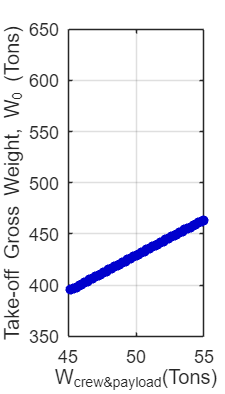

% Plot
figure(1);

clf;

plot(W_cp ./ 1000, W0_solution ./ 1000, '.', 'MarkerSize', 20, 'Color', [0/255 0/255 205/255]);

xlabel('W_{crew&payload}(Tons)');    
ylabel('Take-off Gross Weight, W_{0} (Tons)'); 

% xlim([30 220]);
ylim([350 650]);

set(gca, 'FontSize', 12)             % set the fontsize of the axis

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 200 350]); % show plot with larger size

### C2 - ${\left(\frac{L}{D}\right)}_{\max }$

% House Keeping
clear
clc

**Basic Parameters**

% Weight
W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8

% W_0 = 0;                               % Takeoff gross weight (kg)
% W_f_0 = 0;                             % W_fuel / W_0
% W_e_0 = 0;                             % W_empty weight / W_0

g = 9.80665;                             % Standard acceleration of gravity (m/s^2)

**Empirical **$\frac{{\mathit{\mathbf{W}}}_{\mathit{\mathbf{f}}} }{{\mathit{\mathbf{W}}}_0 }$** Data**

% Warmup and Takeoff
W_TO_Ry = 0.970;                 % W_i / W_i-1 % Raymer p.34
W_TO_Rk = 0.99 .* 0.99 .* 0.995; % W_i / W_i-1 % Roskam Part I p.12

% Climb and Accelerate to cruise
W_C_Ry = 0.985;                  % W_i / W_i-1 % Raymer p.34
W_C_Rk = 0.980;                  % W_i / W_i-1 % Roskam Part I p.12

% Descent to land
W_D_Ry = 0.990; % 0.990 to 0.995 % W_i / W_i-1 % Raymer p.153
W_D_Rk = 0.990;                  % W_i / W_i-1 % Roskam Part I p.12

% Landing and Taxi
W_L_Ry = 0.992; % 0.992 to 0.997 % W_i / W_i-1 % Raymer p.34 (p.153)
W_L_Rk = 0.992;                  % W_i / W_i-1 % Roskam Part I p.12

**Empirical Airplane Data**

AR = 8;            % Aspect ratio        % Respectively, a lower Aspect Ratio has been chosen since the Reference Code 4E and also reduce structural challenge
WR = 4.5;          % S_wet / S_ref       % Raymer p.40 we read from the graph
AR_W = AR ./ WR;   % Wetted aspect ratio
K_LD = 15.5;       % For civil jets      % Raymer p.40

% LD_max = K_LD .* (AR_W) .^ 0.5;     % L/D_max       % Raymer p.41

% Guess L/D_max
LD_max = zeros(1, 50);

for i = 1:50
    LD_max(i) = 17.5 + 0.08 * i;
end

LD_cruise = 0.866 .* LD_max;        % L/D_cruise    % Raymer p.41
LD_alternate = (10 / 18) .* LD_max; % L/D_alternate % Roskam p.57

**Empirical Engine Data**

NE = 4; % Number of engines

High-bypass Turbofan

% C_cruise = 0.5 ./ 3600; % SFC (1/s) % Raymer p.36
% C_loiter = 0.4 ./ 3600; % SFC (1/s) % Raymer p.36

GE9X

% W_engine = 9630; % Weight of engine (kg)
% T_0 = 489300;    % Takeoff thrust (N)
% T_0 = T_0 * 1.05;% Rubber engine
% T_c = TBD;       % Maximum continuous thrust (N)
% BPR = 10;          % Bypass Ratio % GE9X % Wikipedia

% C_cruise = (0.478 .* 0.95) ./ 3600; % SFC (1/s) % 5% lower SFC than the XWB-97 % Wikipedia
% C_loiter = 0.8 .* C_cruise;         % SFC (1/s) % 80% cruise SFC  % Raymer p.36
% C_alternate = 1.15 .* C_cruise;     % SFC (1/s) % 115% cruise SFC % Ref12

Trent 972E-84 

% W_engine = 9630; % Weight of engine (kg)
T_0 = 320300;      % Takeoff thrust (N)
T_0 = T_0 * 1.05;  % Rubber engine
% T_c = TBD;       % Maximum continuous thrust (N)
BPR = 8.5;         % Bypass Ratio % Trent 972E-84 % Ref 17

C_cruise = 0.5 ./ 3600;         % SFC (1/s) % Raymer p.36
C_loiter = 0.4 ./ 3600;         % SFC (1/s) % Raymer p.36
C_alternate = 1.15 .* C_cruise; % SFC (1/s) % 115% cruise SFC % Ref12
% C_alternate =  C_cruise; % SFC (1/s) % 115% cruise SFC % Ref12

% Housekeeping
clearvars WR AR_W K_LD i

**Calculate Fuel Fraction **

**0-1** Taxi & Takeoff

W_10_Ry = W_TO_Ry;
W_10_Rk = W_TO_Rk;

**1-2** Climb and accelerate to cruise

W_21_Ry = W_C_Ry;
W_21_Rk = W_C_Rk;

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Cruise altitude 39,000 ft align with Boeing 777 % Wikipedia

R_32 = convlength(7500, 'naut mi','m'); % Range (m)
h_32 = convlength(39000, 'ft','m');     % Cruise altitude (m)

[T_32, c_32, P_32, rho_32] = atmosisa(h_32);

V_32 = 0.83 * c_32;                     % Velocity (m/s)
LD_32 = LD_cruise;                      % Optimal cruise L/D ratio

% Breguet range equation
W_32 = exp((-R_32 .* C_cruise) ./ (V_32 .* LD_32));

**3-4** Descent to land

W_43_Ry = W_D_Ry;
W_43_Rk = W_D_Rk;

**4-5** Missed approach, followed by clmb and accelerate to alternate

W_54_Ry = W_C_Ry;
W_54_Rk = W_C_Rk;

**5-6** Cruise to alternate destination 370 km away

% Cruise altitude 18,000 ft for Lost Communications Missed Approach % Ref 5
% Assume cruise velocity 400 knots                                  % Ref 5

R_65 = convlength(370, 'km', 'm');  % Range (m)
h_65 = convlength(18000, 'ft','m'); % Alternate altitude (m)

% [T_65, c_65, P_65, rho_65] = atmosisa(h_65);

V_65 = convvel(400, 'kts', 'm/s');  % Alternate velocity (m/s)
LD_65 = LD_alternate;               % Estimate alternate L/D ratio

% Breguet range equation
W_65 = exp((-R_65 .* C_alternate) ./ (V_65 .* LD_65));

**6-7** Loiter at 5000 ft for 45 minutes

E_76 = 45 * 60; % Endurance (s)
LD_76 = LD_max; % Optimal loiter L/D ratio

% Breguet endurance equation
W_76 = exp((-E_76 .* C_loiter) ./ LD_76);

**7-8** Descent to land

W_87_Ry = W_D_Ry;
W_87_Rk = W_D_Rk;

**8-9** Landing & Taxi

W_98_Ry = W_L_Ry;
W_98_Rk = W_L_Rk;

Plot table for fuel fraction 

% col1 = ["0-1", "1-2", "2-3", "3-4", "4-5", "5-6", "6-7", "7-8", "8-9"];
% col2 = [W_10_Ry, W_21_Ry, W_32, W_43_Ry, W_54_Ry, W_65, W_76, W_87_Ry, W_98_Ry];
% col3 = cumprod(col2);
% col4 = [W_10_Rk, W_21_Rk, W_32, W_43_Rk, W_54_Rk, W_65, W_76, W_87_Rk, W_98_Rk];
% col5 = cumprod(col4);
% T = table(col1', col2', col3', col4', col5', 'VariableNames', ...
   % {'Leg', 'Wi/Wi-1 (Raymer)', 'Culmulative (Raymer)', 'Wi/Wi-1 (Roskam)', 'Culmulative (Roskam)'});
% disp(T)

Culmulative fuel fraction


$$\frac{W_f }{W_0 }=1\ldotp 01\left(1-\frac{W_x }{W_0 }\right)$$


W_f_0_Ry = 1.01 .* (1 - W_10_Ry .* W_21_Ry .* W_32 .* W_43_Ry .* W_54_Ry .* W_65 .* W_76 .* W_87_Ry .* W_98_Ry)

W_f_0_Ry =     0.4842    0.4828    0.4815    0.4801    0.4788    0.4775    0.4762    0.4749    0.4736    0.4724    0.4711    0.4698    0.4686    0.4673    0.4661    0.4649    0.4636    0.4624    0.4612    0.4600    0.4588    0.4576    0.4565    0.4553    0.4541    0.4530    0.4518    0.4507    0.4496    0.4484    0.4473    0.4462    0.4451    0.4440    0.4429    0.4418    0.4407    0.4396    0.4386    0.4375    0.4365    0.4354    0.4344    0.4333    0.4323    0.4313    0.4302    0.4292    0.4282    0.4272


W_f_0_Rk = 1.01 .* (1 - W_10_Rk .* W_21_Rk .* W_32 .* W_43_Rk .* W_54_Rk .* W_65 .* W_76 .* W_87_Rk .* W_98_Rk)

W_f_0_Rk =     0.4867    0.4853    0.4840    0.4827    0.4814    0.4801    0.4788    0.4775    0.4762    0.4749    0.4737    0.4724    0.4712    0.4699    0.4687    0.4675    0.4663    0.4651    0.4639    0.4627    0.4615    0.4603    0.4591    0.4580    0.4568    0.4557    0.4545    0.4534    0.4523    0.4511    0.4500    0.4489    0.4478    0.4467    0.4456    0.4445    0.4435    0.4424    0.4413    0.4403    0.4392    0.4382    0.4371    0.4361    0.4351    0.4340    0.4330    0.4320    0.4310    0.4300


% Store Value into Matrix
W_i = [W_10_Ry W_21_Ry W_32 W_43_Ry W_54_Ry W_65 W_76 W_87_Ry W_98_Ry]; % Raymer
% W_i = [W_10_Rk W_21_Rk W_32 W_43_Rk W_54_Rk W_65 W_76 W_87_Rk W_98_Rk]; % Roskam

% Housekeeping
clearvars R_32 V_32 LD_32 h_32 T_32 c_32 P_32 rho_32
clearvars R_65 V_65 LD_65 h_65 % T_65 c_32 P_65 rho_65
clearvars E_76 LD_76
clearvars W_10_Ry W_10_Rk W_21_Ry W_21_Rk W_32 W_43_Ry W_43_Rk W_54_Ry W_54_Rk
clearvars W_65 W_76 W_87_Ry W_87_Rk W_98_Ry W_98_Rk
clearvars col1 col2 col3 col4 col5 T
clearvars W_TO_Ry W_TO_Rk W_C_Ry W_C_Rk W_D_Ry W_D_Rk W_L_Ry W_L_Rk

**Calculate Empty Weight Fraction**

From regression of historical data (Raymer p.31)

A = 0.97;  % Constant from jet transport historical data % Raymer p.31
C = -0.06; % Constant from jet transport historical data % Raymer p.31
% W_e_0_His = A .* W_0 .^ C;

**Estimate Takeoff Gross Weight**

We need solution satisfies both equations below

- $\frac{W_e }{W_0 }={{\textrm{AW}}_0 }^C$ (from regression of historical data)

- 
$$W_0 =\frac{W_{\textrm{crew}} +W_{\textrm{payload}} }{1-\frac{W_f }{W_0 }-\frac{W_e }{W_0 }}$$


Therefore,


$$W_0 =\frac{W_{\textrm{crew}} +W_{\textrm{payload}} }{1-\frac{W_f }{W_0 }-{{\textrm{AW}}_0 }^C }$$


Find the cross empty weight

for i = 1:50

    func = @(W0) ((W_crew + W_payload) / (1 - W_f_0_Ry(i) - A * W0 ^ C)) - W0; % Define the function to solve for W0
    
    W0_initial_guess = 4000000;  % Adjust based on expected range
    
    W0_solution(i) = fsolve(func, W0_initial_guess);

end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

Plot the result

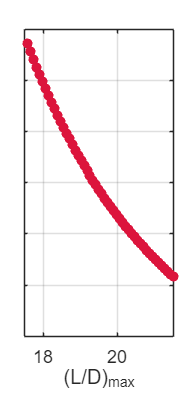

% Plot
figure(2);

clf;

plot(LD_max, W0_solution ./ 1000, '.', 'MarkerSize', 20, 'Color', [220/255 20/255 60/255]);

xlabel('(L/D)_{max}');    
% ylabel('Take-off Gross Weight, W_{0} (Tons)'); 

set(gca,'yticklabel',[])

xlim([17.5 21.5]);
ylim([350 650]);

set(gca, 'FontSize', 12)             % set the fontsize of the axis

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 170 350]); % show plot with larger size

### C3 - C

% House Keeping
clear
clc

**Basic Parameters**

% Weight
W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8

% W_0 = 0;                               % Takeoff gross weight (kg)
% W_f_0 = 0;                             % W_fuel / W_0
% W_e_0 = 0;                             % W_empty weight / W_0

g = 9.80665;                             % Standard acceleration of gravity (m/s^2)

**Empirical **$\frac{{\mathit{\mathbf{W}}}_{\mathit{\mathbf{f}}} }{{\mathit{\mathbf{W}}}_0 }$** Data**

% Warmup and Takeoff
W_TO_Ry = 0.970;                 % W_i / W_i-1 % Raymer p.34
W_TO_Rk = 0.99 .* 0.99 .* 0.995; % W_i / W_i-1 % Roskam Part I p.12

% Climb and Accelerate to cruise
W_C_Ry = 0.985;                  % W_i / W_i-1 % Raymer p.34
W_C_Rk = 0.980;                  % W_i / W_i-1 % Roskam Part I p.12

% Descent to land
W_D_Ry = 0.990; % 0.990 to 0.995 % W_i / W_i-1 % Raymer p.153
W_D_Rk = 0.990;                  % W_i / W_i-1 % Roskam Part I p.12

% Landing and Taxi
W_L_Ry = 0.992; % 0.992 to 0.997 % W_i / W_i-1 % Raymer p.34 (p.153)
W_L_Rk = 0.992;                  % W_i / W_i-1 % Roskam Part I p.12

**Empirical Airplane Data**

AR = 8;            % Aspect ratio        % Respectively, a lower Aspect Ratio has been chosen since the Reference Code 4E and also reduce structural challenge
WR = 4.5;          % S_wet / S_ref       % Raymer p.40 we read from the graph
AR_W = AR ./ WR;   % Wetted aspect ratio
K_LD = 15.5;       % For civil jets      % Raymer p.40

LD_max = K_LD .* (AR_W) .^ 0.5;     % L/D_max       % Raymer p.41
LD_cruise = 0.866 .* LD_max;        % L/D_cruise    % Raymer p.41
LD_alternate = (10 / 18) .* LD_max; % L/D_alternate % Roskam p.57

**Empirical Engine Data**

NE = 4; % Number of engines

High-bypass Turbofan

% C_cruise = 0.5 ./ 3600; % SFC (1/s) % Raymer p.36
% C_loiter = 0.4 ./ 3600; % SFC (1/s) % Raymer p.36

GE9X

% W_engine = 9630; % Weight of engine (kg)
% T_0 = 489300;    % Takeoff thrust (N)
% T_0 = T_0 * 1.05;% Rubber engine
% T_c = TBD;       % Maximum continuous thrust (N)
% BPR = 10;          % Bypass Ratio % GE9X % Wikipedia

% C_cruise = (0.478 .* 0.95) ./ 3600; % SFC (1/s) % 5% lower SFC than the XWB-97 % Wikipedia
% C_loiter = 0.8 .* C_cruise;         % SFC (1/s) % 80% cruise SFC  % Raymer p.36
% C_alternate = 1.15 .* C_cruise;     % SFC (1/s) % 115% cruise SFC % Ref12

Trent 972E-84 

% W_engine = 9630; % Weight of engine (kg)
T_0 = 320300;      % Takeoff thrust (N)
T_0 = T_0 * 1.05;  % Rubber engine
% T_c = TBD;       % Maximum continuous thrust (N)
BPR = 8.5;         % Bypass Ratio % Trent 972E-84 % Ref 17

% Guess C_cruise
C_cruise = zeros(1, 50);

for i = 1:50
    C_cruise(i) = 0.45 + (3 ./ 1000) * i;
end

C_cruise = C_cruise ./ 3600;

% C_cruise = 0.5 ./ 3600;         % SFC (1/s) % Raymer p.36
C_loiter = 0.4 ./ 3600;         % SFC (1/s) % Raymer p.36
C_alternate = 1.15 .* C_cruise; % SFC (1/s) % 115% cruise SFC % Ref12
% C_alternate =  C_cruise; % SFC (1/s) % 115% cruise SFC % Ref12

% Housekeeping
clearvars WR AR_W K_LD i

**Calculate Fuel Fraction **

**0-1** Taxi & Takeoff

W_10_Ry = W_TO_Ry;
W_10_Rk = W_TO_Rk;

**1-2** Climb and accelerate to cruise

W_21_Ry = W_C_Ry;
W_21_Rk = W_C_Rk;

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Cruise altitude 39,000 ft align with Boeing 777 % Wikipedia

R_32 = convlength(7500, 'naut mi','m'); % Range (m)
h_32 = convlength(39000, 'ft','m');     % Cruise altitude (m)

[T_32, c_32, P_32, rho_32] = atmosisa(h_32);

V_32 = 0.83 * c_32;                     % Velocity (m/s)
LD_32 = LD_cruise;                      % Optimal cruise L/D ratio

% Breguet range equation
W_32 = exp((-R_32 .* C_cruise) ./ (V_32 .* LD_32));

**3-4** Descent to land

W_43_Ry = W_D_Ry;
W_43_Rk = W_D_Rk;

**4-5** Missed approach, followed by clmb and accelerate to alternate

W_54_Ry = W_C_Ry;
W_54_Rk = W_C_Rk;

**5-6** Cruise to alternate destination 370 km away

% Cruise altitude 18,000 ft for Lost Communications Missed Approach % Ref 5
% Assume cruise velocity 400 knots                                  % Ref 5

R_65 = convlength(370, 'km', 'm');  % Range (m)
h_65 = convlength(18000, 'ft','m'); % Alternate altitude (m)

% [T_65, c_65, P_65, rho_65] = atmosisa(h_65);

V_65 = convvel(400, 'kts', 'm/s');  % Alternate velocity (m/s)
LD_65 = LD_alternate;               % Estimate alternate L/D ratio

% Breguet range equation
W_65 = exp((-R_65 .* C_alternate) ./ (V_65 .* LD_65));

**6-7** Loiter at 5000 ft for 45 minutes

E_76 = 45 * 60; % Endurance (s)
LD_76 = LD_max; % Optimal loiter L/D ratio

% Breguet endurance equation
W_76 = exp((-E_76 .* C_loiter) ./ LD_76);

**7-8** Descent to land

W_87_Ry = W_D_Ry;
W_87_Rk = W_D_Rk;

**8-9** Landing & Taxi

W_98_Ry = W_L_Ry;
W_98_Rk = W_L_Rk;

Plot table for fuel fraction 

% col1 = ["0-1", "1-2", "2-3", "3-4", "4-5", "5-6", "6-7", "7-8", "8-9"];
% col2 = [W_10_Ry, W_21_Ry, W_32, W_43_Ry, W_54_Ry, W_65, W_76, W_87_Ry, W_98_Ry];
% col3 = cumprod(col2);
% col4 = [W_10_Rk, W_21_Rk, W_32, W_43_Rk, W_54_Rk, W_65, W_76, W_87_Rk, W_98_Rk];
% col5 = cumprod(col4);
% T = table(col1', col2', col3', col4', col5', 'VariableNames', ...
   % {'Leg', 'Wi/Wi-1 (Raymer)', 'Culmulative (Raymer)', 'Wi/Wi-1 (Roskam)', 'Culmulative (Roskam)'});
% disp(T)

Culmulative fuel fraction


$$\frac{W_f }{W_0 }=1\ldotp 01\left(1-\frac{W_x }{W_0 }\right)$$


W_f_0_Ry = 1.01 .* (1 - W_10_Ry .* W_21_Ry .* W_32 .* W_43_Ry .* W_54_Ry .* W_65 .* W_76 .* W_87_Ry .* W_98_Ry)

W_f_0_Ry =     0.4124    0.4140    0.4157    0.4174    0.4190    0.4207    0.4223    0.4239    0.4256    0.4272    0.4288    0.4304    0.4321    0.4337    0.4353    0.4369    0.4385    0.4401    0.4417    0.4432    0.4448    0.4464    0.4480    0.4495    0.4511    0.4527    0.4542    0.4558    0.4573    0.4588    0.4604    0.4619    0.4634    0.4650    0.4665    0.4680    0.4695    0.4710    0.4725    0.4740    0.4755    0.4770    0.4785    0.4800    0.4814    0.4829    0.4844    0.4858    0.4873    0.4888


W_f_0_Rk = 1.01 .* (1 - W_10_Rk .* W_21_Rk .* W_32 .* W_43_Rk .* W_54_Rk .* W_65 .* W_76 .* W_87_Rk .* W_98_Rk)

W_f_0_Rk =     0.4153    0.4169    0.4186    0.4202    0.4219    0.4235    0.4251    0.4268    0.4284    0.4300    0.4316    0.4332    0.4349    0.4365    0.4381    0.4396    0.4412    0.4428    0.4444    0.4460    0.4475    0.4491    0.4507    0.4522    0.4538    0.4553    0.4569    0.4584    0.4600    0.4615    0.4630    0.4646    0.4661    0.4676    0.4691    0.4706    0.4721    0.4736    0.4751    0.4766    0.4781    0.4796    0.4810    0.4825    0.4840    0.4855    0.4869    0.4884    0.4898    0.4913


% Store Value into Matrix
W_i = [W_10_Ry W_21_Ry W_32 W_43_Ry W_54_Ry W_65 W_76 W_87_Ry W_98_Ry]; % Raymer
% W_i = [W_10_Rk W_21_Rk W_32 W_43_Rk W_54_Rk W_65 W_76 W_87_Rk W_98_Rk]; % Roskam

% Housekeeping
clearvars R_32 V_32 LD_32 h_32 T_32 c_32 P_32 rho_32
clearvars R_65 V_65 LD_65 h_65 % T_65 c_32 P_65 rho_65
clearvars E_76 LD_76
clearvars W_10_Ry W_10_Rk W_21_Ry W_21_Rk W_32 W_43_Ry W_43_Rk W_54_Ry W_54_Rk
clearvars W_65 W_76 W_87_Ry W_87_Rk W_98_Ry W_98_Rk
clearvars col1 col2 col3 col4 col5 T
clearvars W_TO_Ry W_TO_Rk W_C_Ry W_C_Rk W_D_Ry W_D_Rk W_L_Ry W_L_Rk

**Calculate Empty Weight Fraction**

From regression of historical data (Raymer p.31)

A = 0.97;  % Constant from jet transport historical data % Raymer p.31
C = -0.06; % Constant from jet transport historical data % Raymer p.31
% W_e_0_His = A .* W_0 .^ C;

**Estimate Takeoff Gross Weight**

We need solution satisfies both equations below

- $\frac{W_e }{W_0 }={{\textrm{AW}}_0 }^C$ (from regression of historical data)

- 
$$W_0 =\frac{W_{\textrm{crew}} +W_{\textrm{payload}} }{1-\frac{W_f }{W_0 }-\frac{W_e }{W_0 }}$$


Therefore,


$$W_0 =\frac{W_{\textrm{crew}} +W_{\textrm{payload}} }{1-\frac{W_f }{W_0 }-{{\textrm{AW}}_0 }^C }$$


Find the cross empty weight

for i = 1:50

    func = @(W0) ((W_crew + W_payload) / (1 - W_f_0_Ry(i) - A * W0 ^ C)) - W0; % Define the function to solve for W0
    
    W0_initial_guess = 4000000;  % Adjust based on expected range
    
    W0_solution(i) = fsolve(func, W0_initial_guess);

end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

Plot the result

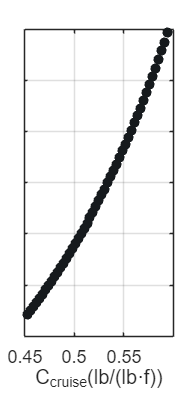

% Plot
figure(3);

clf;

plot(C_cruise .* 3600, W0_solution ./ 1000, '.', 'MarkerSize', 20, 'Color', [22/255 26/255 29/255]);

xlabel('C_{cruise}(lb/(lb·f))');    
% ylabel('Take-off Gross Weight, W_{0} (Tons)'); \

set(gca,'yticklabel',[])

xlim([0.45 0.6]);
ylim([350 650]);

set(gca, 'FontSize', 12)             % set the fontsize of the axis

grid on;                             % set the grid of the graph

set(gcf, 'Position', [0 0 170 350]); % show plot with larger size
